# Symulacja zbiornika ze stałym wypływem i grzaniem

#### Mateusz Wójcik, 4.12.2024

## 1.Cele ćwiczenia

Celem ćwiczenia jest zamodelowanie zbiornika ze stałym wypływem i grzaniem cieczy. Symulacja opiera się na rozwiązywaniu równań różniczkowych opisujących model zbiornika metodą Eulera w środowisku Matlab.

## 2. Model matematyczny

W trakcie modelowania zbiornika przyjęto założenie idealnego mieszania się cieczy. Model takiego zbiornika ze stałym dopływem, wypływem i grzaniem opisany jest dwoma podstawowymi równaniami:

**Zasadą zachowania masy:**

$\rho \frac{dV}{dt} = w_i - w$,

oraz **zasadą zachowania energii:**


$$V \rho \frac{dT}{dt} = w_i(T_i-T) + \frac{Q}{C}$$


Poniżej przedstawiono uproszczony schemat zbiornika, który zaczerpnięto z konspektu, z którym pracowano na zajęciach laboratoryjnych.

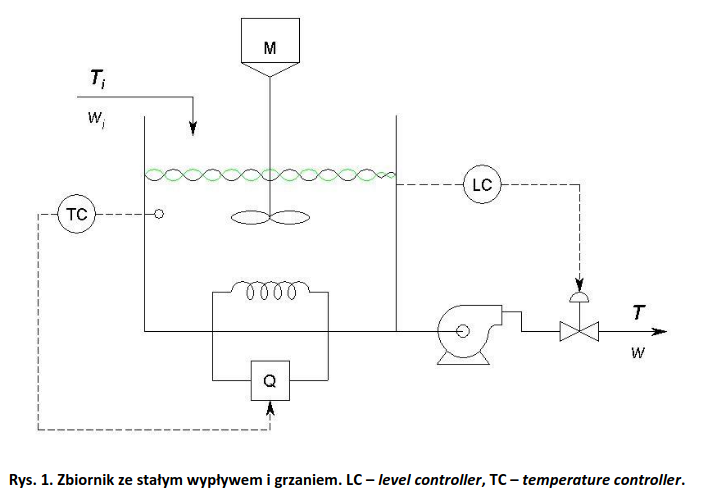

Kolejnym krokiem było zdefiniowanie zmiennych oraz wyznaczenie brakujących elementów oraz przejście do wykonywania różnych symulacji.

clear, clf
N = 10000;      %liczba próbek
h = 0.1;         %okres próbkowania – 10 próbek to jedna sekunda
Q_max = 25000;   %[W] moc maksymalna grzałki
w_ust = 0.4;     %[kg/s] przepływ w stanie ustalonym
T_i = 293;       %[K] temperatura cieczy wlotowej
T_ust = 303;     %[K] temperatura cieczy wylotowej w stanie ustalonym
V_ust = 0.04;    %[m3] objętość w stanie ustalonym
C = 4200;        %[J/(KgK)] ciepło właściwe wody =1000 [Kyg/m3] gęstość wod
rho = 1000;       %[kg/m3] gęstość cieczy

% Początkowe nastawy wpływu i wypływu
w_i = w_ust;
w = w_ust;

Aby wyznaczyć moc w stanie ustalonym skorzystano z wcześniejszych równań różniczkowych, dokładnie z zasady zachowania energii. Tam zamiast pochodnej $\frac{dT}{dt}$ przyjęto wartość 0, ponieważ w stanie ustalonym temperatura przyjmuje stałą wartość. Po przekształceniach otrzymano wzór:

$Q_{ust} = w_i \cdot C \cdot (T-T_i)$,

na podstawie którego wyznaczono wartość parametru w Matlabie:

Q_ust = w_ust*C*(T_ust-T_i)

Q_ust = 16800

## 3. Symulacje

Na podstawie wcześniej utworzonego modelu matematycznego utworzono szereg symulacji, korzystająć z metody Eulera. Zdecydowano się na użycie tej metody, nawet pomimo wcześniejszych zajęć laboratoryjnych, na których wskazano jej wady. Przyczyną takiego wyboru jest pełna kontrola nad napisanym kodem i możliwość prostego wprowadzania modyfikacji w celu zaobserwowania pewnych zjawisk.

Pierwszą symulację przeprowadzono dla stałej wartości objętości, przepływu i mocy w stanie ustalonym. Wyniki wykonanych obliczeń przedstawiono na poniższym wykresie.

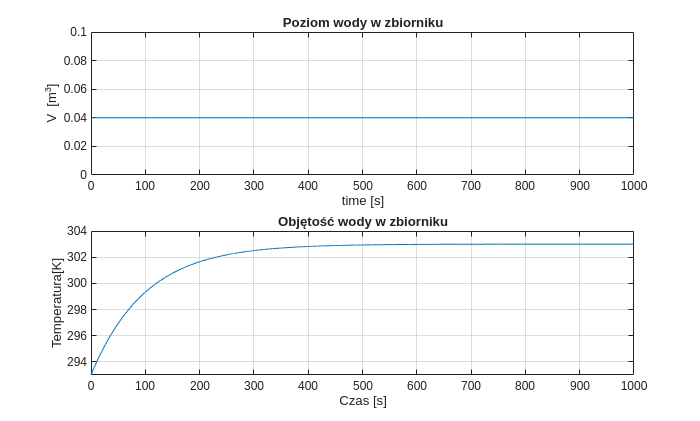

V = zeros(1,N);
T = zeros(1,N);
V(1) = V_ust;
T(1) = T_i;

t =(0:N-1)*h;

for i = 1:(N-1)
    dV = (w_i- w)/rho;
    V(i+1) = V(i) + dV * h;
    dT = (w_i*(T_i - T(i)) + Q_ust/C)/(V(i)*rho);
    T(i+1) = T(i) + dT*h;
end
figure()
subplot(2,1,1)
plot(t,V)
grid on 
title("Poziom wody w zbiorniku")
xlabel("time [s]")
ylabel("V [m^3]")
axis([0,N*h, 0, 0.1])

subplot(2,1,2)
plot(t,T)
grid on 
title("Objętość wody w zbiorniku")
xlabel("Czas [s]")
ylabel("Temperatura[K]")

W następnych symulacjach zastosowano zmienny przebieg mocy dostarczanej przez grzałkę, który był podzielony na 5 okresów, w których moc przyjmowała pewną stała wartość. Z nowym przebiegiem wartości mocy dostarczanej do zbiornika zasymulowana następujące przypadki:

#### Rózna prędkość przepływu i stała objętość

X = ones(1,floor(N/5));
Q = [Q_ust*X, 0.5*Q_ust*X, Q_ust*X, 1.5*Q_ust*X, Q_ust*X];
% Początkowe nastawy wpływu i wypływu
w_i = [w_ust, 1.25*w_ust, 1.5*w_ust];
w = [w_ust, 1.25*w_ust, 1.5*w_ust];

V = zeros(1,N);
T = zeros(3,N);
V(1) = V_ust;
T(:,1) = T_i;

t =(0:N-1)*h;
for i = 1:(N-1)
    for j = 1:length(w)
        dV = (w_i(j)- w(j))/rho;
        V(i+1) = V(i) + dV * h;
        dT = (w_i(j)*(T_i - T(j,i)) + Q(i)/C)/(V(i)*rho);
        T(j,i+1) = T(j,i) + dT*h;
    end
end


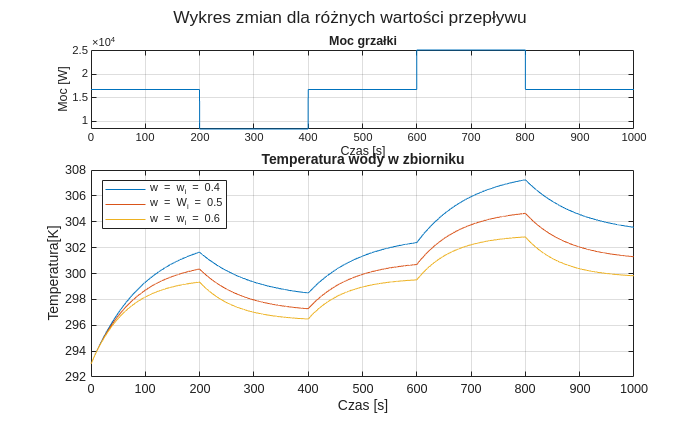

figure();

subplot(3,1,1)
plot(t,Q)
grid on 
title("Moc grzałki")
xlabel("Czas [s]")
ylabel("Moc [W]")

subplot(3,1,[2,3])
plot(t,T)
grid on 
title("Temperatura wody w zbiorniku")
xlabel("Czas [s]")
ylabel("Temperatura[K]")
legend(["w = w_i = 0.4", "w = W_i = 0.5", "w = w_i = 0.6"], Location="northwest")

sgtitle("Wykres zmian dla różnych wartości przepływu")

#### Stała prędkość przepływu i różna objętość

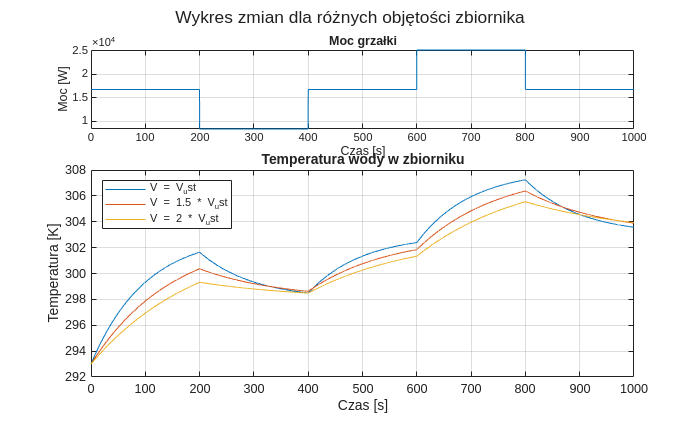

w_i = w_ust;
w = w_ust;

V_0 = [V_ust; 1.5*V_ust; 2*V_ust];

V = zeros(3,N);
T = zeros(3,N);
V(:,1) = V_0;
T(:,1) = T_i;

t =(0:N-1)*h;
for i = 1:(N-1)
        dV = (w_i- w)/rho;
        V(:,i+1) = V(:,i) + dV * h;
        dT = (w_i*(T_i - T(:,i)) + Q(i)/C);
        dT = dT./(V(:,i)*rho);
        T(:,i+1) = T(:,i) + dT*h;
end

figure

subplot(3,1,1)
plot(t,Q)
grid on 
title("Moc grzałki")
xlabel("Czas [s]")
ylabel("MSymulacje potwierdziłyoc [W]")

subplot(3,1,[2,3])
plot(t,T)
grid on 
title("Temperatura wody w zbiorniku")
xlabel("Czas [s]")
ylabel("Temperatura [K]")
legend(["V = V_ust", "V = 1.5 * V_ust", "V = 2 * V_ust"],"Location","northwest")

sgtitle("Wykres zmian dla różnych objętości zbiornika")

#### Rózne wartości strumienia wejściowego i wyjściowego

W tej symulacji zdefiniowno trzy różne zestawy wejściowe dla wartości strumienia wejściowego i wyjściowego, tak aby nie były sobie równe. Wyniki zaprezentowano na poniższych wykresach:

w_i = [w_ust, 1.25*w_ust, 1.5*w_ust];
w = [w_ust, 1.4*w_ust, 1.3*w_ust];

V = zeros(3,N);
T = zeros(3,N);
V(:, 1) = V_ust;
T(:,1) = T_i;

t =(0:N-1)*h;
for i = 1:(N-1)
    for j = 1:length(w)
        dV = (w_i(j)- w(j))/rho;
        V(j,i+1) = calcV(V(j,i), dV, h, V_ust);
        dT = (w_i(j)*(T_i - T(j,i)) + Q(i)/C)/(V(j,i)*rho);
        T(j,i+1) = T(j,i) + dT*h;
    end
end


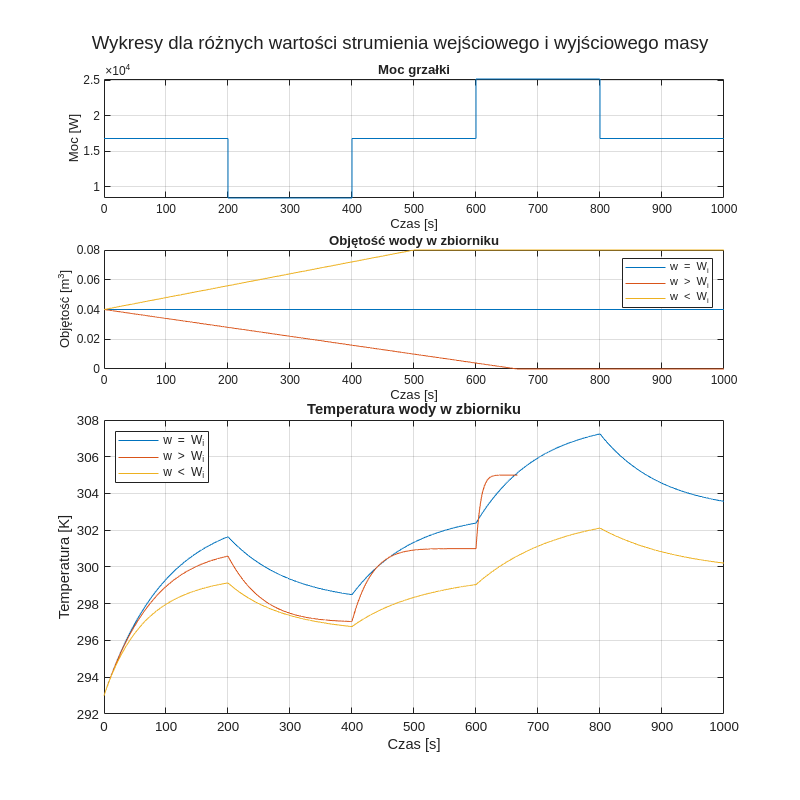

figure(Position=[100 100 800 800])
subplot(4,1,1)
plot(t,Q)
grid on 
title("Moc grzałki")
xlabel("Czas [s]")
ylabel("Moc [W]")

subplot(4,1,2)
plot(t,V)
grid on 
title("Objętość wody w zbiorniku")
xlabel("Czas [s]")
ylabel("Objętość [m^3]")
legend(["w = W_i", "w > W_i", "w < W_i"],"Location","northeast")
subplot(4,1,[3,4])
plot(t,T)
grid on 
title("Temperatura wody w zbiorniku")
xlabel("Czas [s]")
ylabel("Temperatura [K]")
legend(["w = W_i", "w > W_i", "w < W_i"],"Location","northwest")

sgtitle('Wykresy dla różnych wartości strumienia wejściowego i wyjściowego masy');

Poniżej zdefniowano funkcję kontrolującą poziom cieczy w zbiorniku, tzn. zapobiegająca powstawaniu ujemnej objętości i gromadzeniu więcej cieczy niż wynosi objętość zbiornika, którą przyjęto na  dwukrotność objętości ustalonej - V_ust. Funkcję tą wykorzystano w ostatnim przykładzie symulacji.

function V = calcV(V_k, dV, h, V_ust)
    V_k_1 = V_k + dV*h;
    if V_k_1 < 0
        V = 0;
    elseif V_k_1 > 2*V_ust
        V = 2*V_ust;
    else
        V = V_k_1;
    end
end

## Wnioski

Przeprowadzone symulacje zbiornika ze stałym wypływem i grzaniem ukazały kluczowe aspekty dynamiki układów fizycznych oraz skuteczność metody Eulera w rozwiązywaniu równań różniczkowych. Mimo ograniczeń tej metody, prostota jej implementacji i możliwość wprowadzania zmian, pozwoliły na łatwe badanie układu przy różnych parametrach, takich jak zmienna moc grzałki, różne przepływy oraz objętości początkowe. Zaobserwowano, że zmiana wartości przepływów, mocy grzałki, jak i objętości cieczy w zbironiku mają znaczący wpływ na mają istotny wpływ na szybkość zmian temperatury cieczy.Dodatkowo, w zdefiniowanie funkcji pomocniczej zapobiegło niefizycznym wynikom, takim jak ujemna objętość.  Można stwierdzić, że badany model był wystarczający do analizy dynamiki układu, a jego rozbudowa mogłaby uwzględnić bardziej zaawansowane efekty, takie jak straty cieplne, czy nieidealność procesu mieszania. Jest to natomiast komplikacja modelu, która często w pierwszym przybliżeniu nie jest w ogóle potrzebna. Potwierdza to wartość prostych metod numerycznych w analizie procesów przemysłowych.